# MA2011: W3 DC motors

date

ans = '28-Mar-2022'

## State-Space Representation

The order of a system depends on the highest derivative present, in mechanical systems we typically have second-order derivatives due to the acceleration in Netwon's law $f(t) = m \ddot x + b \dot x + k x$ which we can rewrite simply as


$$\ddot x = \frac{-b \dot x -k x +f(t)}{m}$$


However, a different way to present a system is to augment its state, e.g. define 

$v := \dot x$ which also means $\dot v = \ddot x$

and rewrite Newton's law as a pair of equations

- 
$$\dot x = v$$


- 
$$\dot v = \frac{-b v- k x - f(t)}{m} $$


or in matrix format, by defining an augmented state vector $Y = [x \ v]^T$

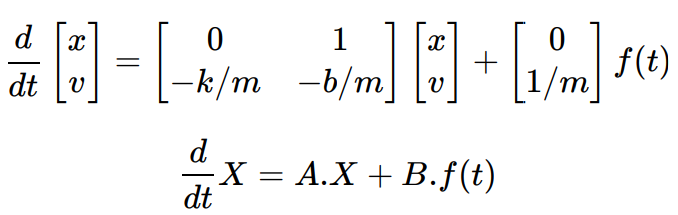

syms x(t) v(t) f(t)
syms m b k real

% augmented state
X = [x; v]

$$X(t) = \left(\begin{array}{c} x\left(t\right)\\ v\left(t\right) \end{array}\right)$$

dXdt = diff(X)

$$dXdt(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ \frac{\partial }{\partial t}v\left(t\right) \end{array}\right)$$

A = [0 1; -k/m -b/m]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{k}{m} & -\frac{b}{m} \end{array}\right)$$

B = [0; 1/m]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{m} \end{array}\right)$$

myNewton = dXdt == A* X + B*f

$$myNewton(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=v\left(t\right)\\ \frac{\partial }{\partial t}v\left(t\right)=\frac{f\left(t\right)}{m}-\frac{b\,v\left(t\right)}{m}-\frac{k\,x\left(t\right)}{m} \end{array}\right)$$

## numerical analysis - try: help ss

m=1, b=0.1, k=1

m = 1

b = 0.1000

k = 1

A = [0 1; -k/m -b/m]

A =          0    1.0000
   -1.0000   -0.1000


B = [0; 1/m]

B =      0
     1


mySystem = ss(A, B, [1 0], 0)

mySystem =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -0.1
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



mySystem.OutputName = {'x'};
mySystem.StateName = {'x', 'v'}

mySystem =
 
  A = 
         x     v
   x     0     1
   v    -1  -0.1
 
  B = 
      u1
   x   0
   v   1
 
  C = 
      x  v
   x  1  0
 
  D = 
      u1
   x   0
 
Continuous-time state-space model.



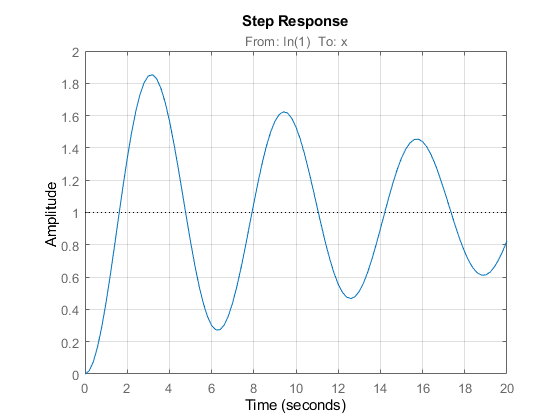

figure
step(mySystem, 20); grid on

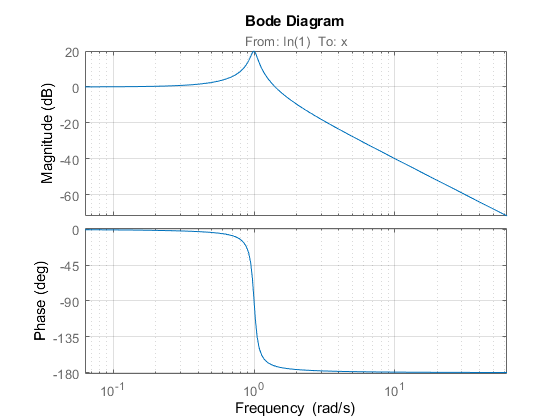

figure
bode(mySystem, {2*pi*1e-2, 2*pi*10}); grid on

## Block Diagram Representation

a general ODE written as 

myNewton

$$myNewton(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=v\left(t\right)\\ \frac{\partial }{\partial t}v\left(t\right)=\frac{f\left(t\right)}{m}-\frac{b\,v\left(t\right)}{m}-\frac{k\,x\left(t\right)}{m} \end{array}\right)$$

m =1, b = 0.1, k = 1

m = 1

b = 0.1000

k = 1

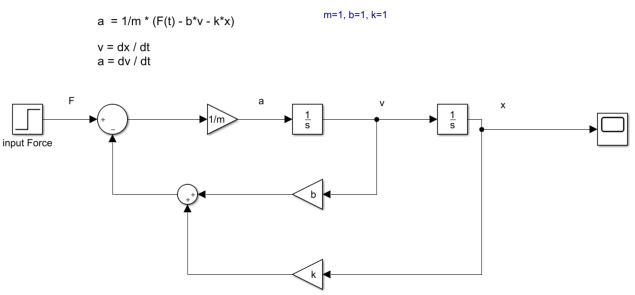

# DC Motor -  State-Space representation

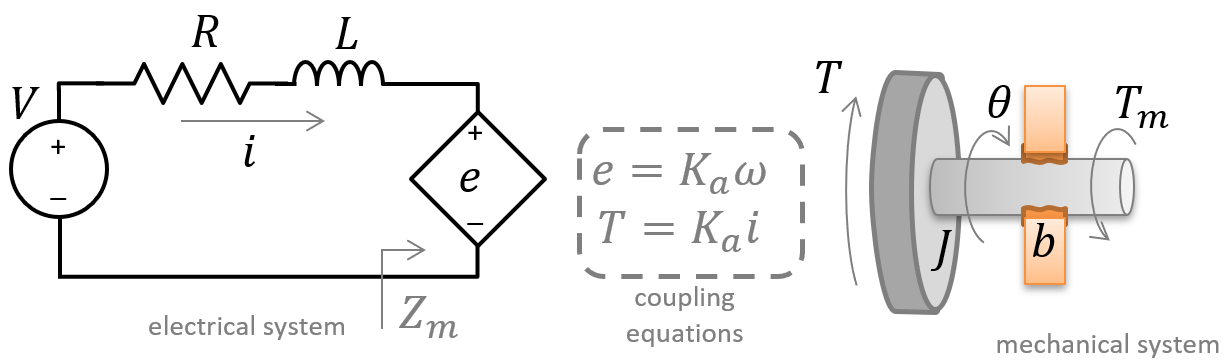

- Mechanical System                 $J\frac{d\omega}{dt}+b\,\omega =T-T_m$

- Electrical system                         $V -e= Ri+L\frac{di}{dt}
$

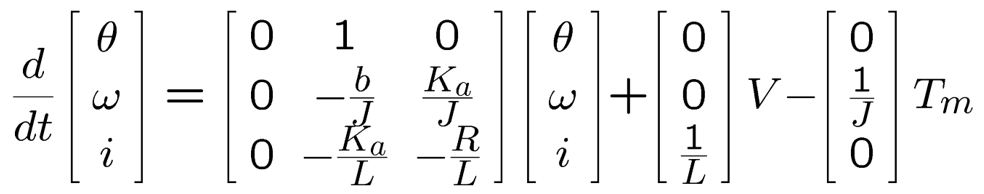

## 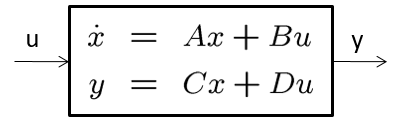

## Analog driving

Consider a motor with a following 

- physical parameters

% PHYSICAL PARAMETERS
J = 3.2284E-6;                   % rotor inertia
b = 3.5077E-6;                   % mech. damping
Ke = 0.0274;                     % e.m.f constant  
R = 4;                           % electric resistance 
L = 2.75E-6;                     % electric inductance 

- A matrix

A=[ 0 1 0;
    0 -b/J  Ke/J;
    0 -Ke/L -R/L;]

A = 	1.0e+06 *

         0    0.0000         0
         0   -0.0000    0.0085
         0   -0.0100   -1.4545


- A matrix eigenvalues

eig(A)'

ans = 	1.0e+06 *

         0   -0.0001   -1.4545


- B input matrix

B=[ 0; 0; 1/L]

B = 	1.0e+05 *

         0
         0
    3.6364


- output matrix ($3\times 3$Identity)

C=eye(3); % y=[theta; omega; i];

- State Space (SS) system definition

myDCM = ss(A,B,C,0);
myDCM.OutputName = {'\theta', '\omega', 'i'};
myDCM.StateName = {'\theta', '\omega', 'i'}

myDCM =
 
  A = 
               \theta      \omega           i
   \theta           0           1           0
   \omega           0      -1.087        8487
   i                0       -9964  -1.455e+06
 
  B = 
                  u1
   \theta          0
   \omega          0
   i       3.636e+05
 
  C = 
           \theta  \omega       i
   \theta       1       0       0
   \omega       0       1       0
   i            0       0       1
 
  D = 
           u1
   \theta   0
   \omega   0
   i        0
 
Continuous-time state-space model.



- system step response

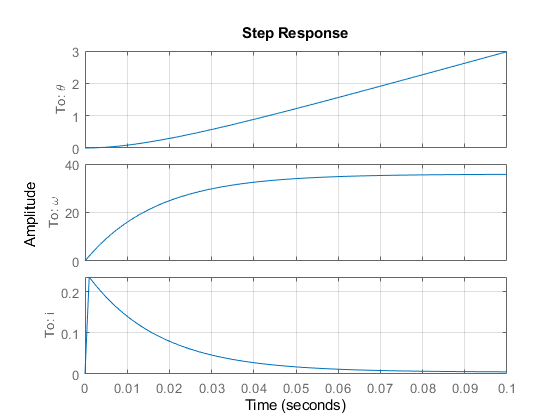

step(myDCM, 0.1), grid on

- system Bode plot

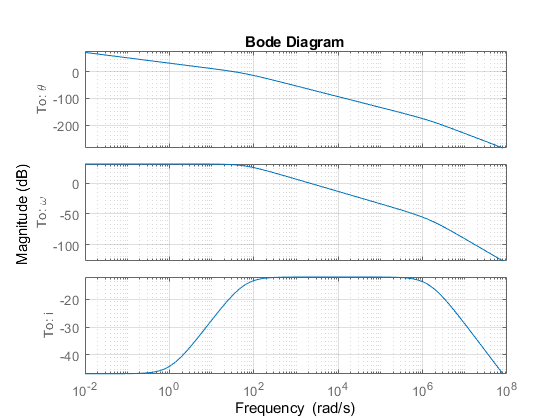

bodemag(myDCM), grid on

# PWM: Pulse Width Modulation

Driving loads such as a DC motor or a heater (which is basically just a high-power resistor) with analog devices, such as a transitor in active region, is usually very inefficient.

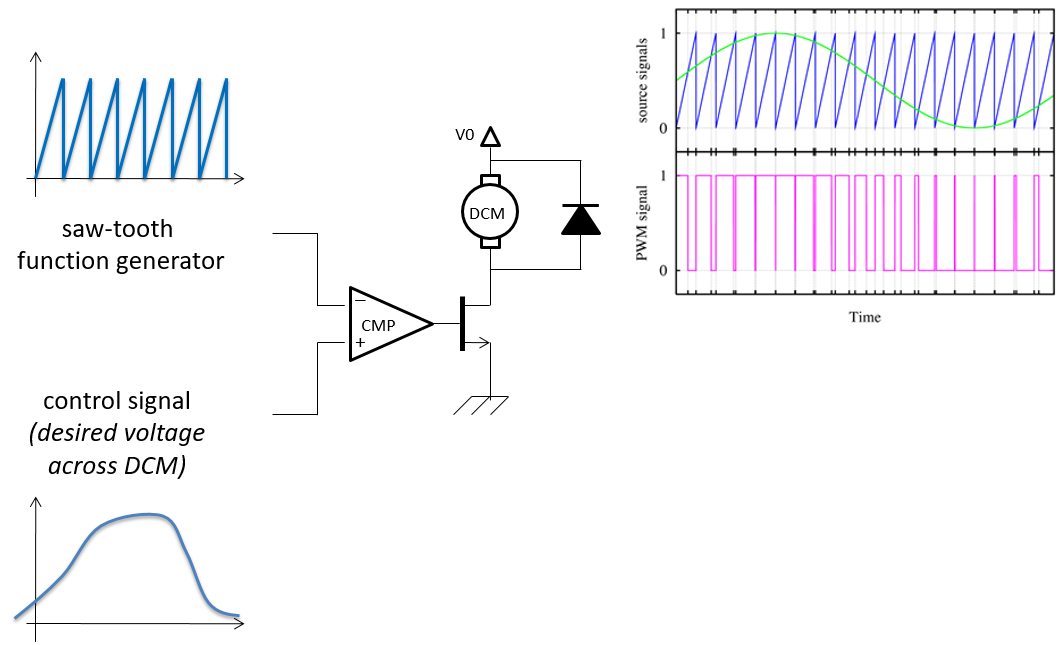

t = 0: 1e-6 : 0.1;

PWM = @(duty, f0, time) duty > mod(f0*time , 1)     %% this function generates a PWM

PWM = function_handle with value:
    @(duty,f0,time)duty>mod(f0*time,1)


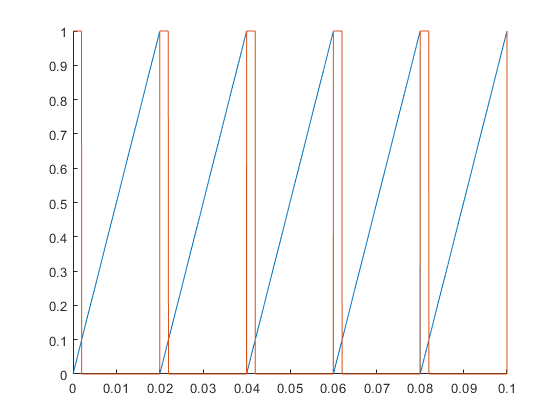

figure
hold on
f0 = 50;
plot(t, mod(f0*t, 1))
plot (t, PWM(.1, f0, t))

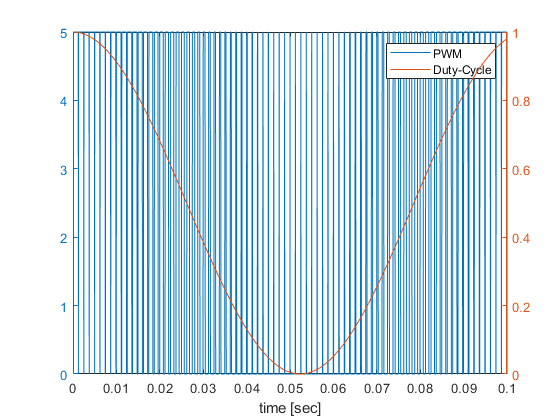

figure
modulating_signal = cos(30*t).^2;
plotyy(t, 5*PWM(modulating_signal , 800, t), t, modulating_signal )
legend('PWM', 'Duty-Cycle')
xlabel('time [sec]')

% now use the PWM to drive your motor

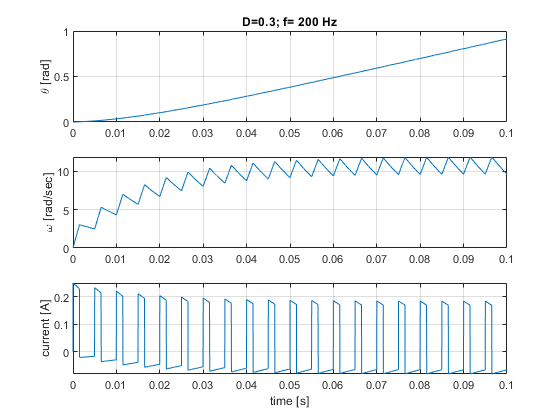

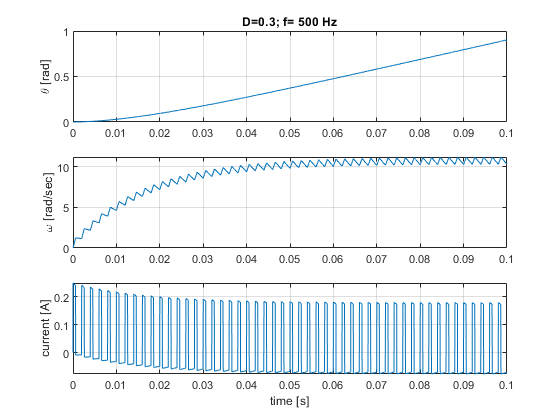

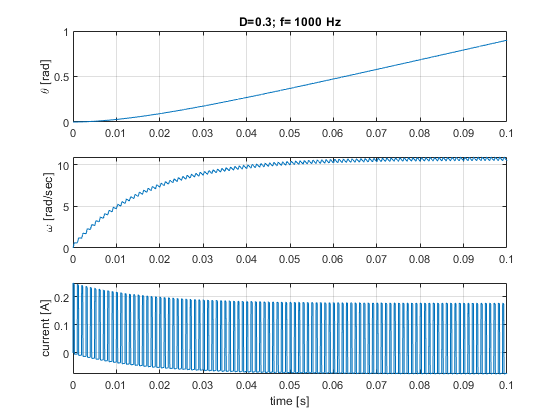


for freq= [200 500 1000]
    duty = 0.3;
    y= lsim(myDCM, 1*PWM(duty, freq, t) ,t);
    theta = y(:,1);
    omega = y(:,2);
    current = y(:,3);
figure;    
    subplot(3,1,1)
    plot(t, theta); ylabel('\theta [rad]'), grid on
    title(['D=' num2str(duty) '; f= ' num2str(freq) ' Hz'])
    subplot(3,1,2)
    plot(t, omega); ylabel('\omega [rad/sec]'), grid on
    subplot(3,1,3)
    plot(t, current); ylabel('current [A]'), grid on
    xlabel('time [s]')
end

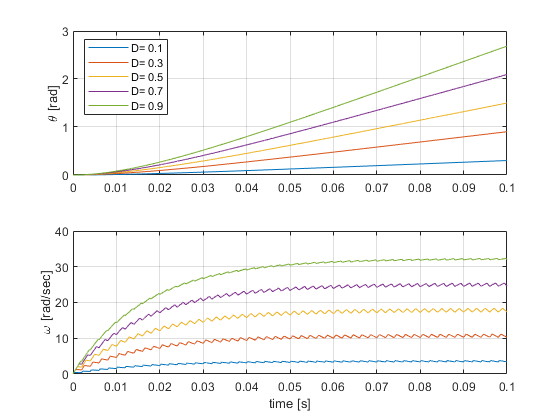



figure
myLegend = {};
for duty= [.1 .3 .5 .7 .9]
    myLegend = {myLegend{:}, ['D= ' num2str(duty)]};
    y= lsim(myDCM, 1*PWM(duty, 500, t) ,t);
    theta = y(:,1);
    omega = y(:,2);
    current = y(:,3);
    subplot(2,1,1)
    plot(t, theta); ylabel('\theta [rad]'), grid on
    hold on
    legend(myLegend, 'Location','northwest')
    subplot(2,1,2)
    plot(t, omega); ylabel('\omega [rad/sec]'), grid on
    xlabel('time [s]')
    hold on
end

# DC Motor: block diagram